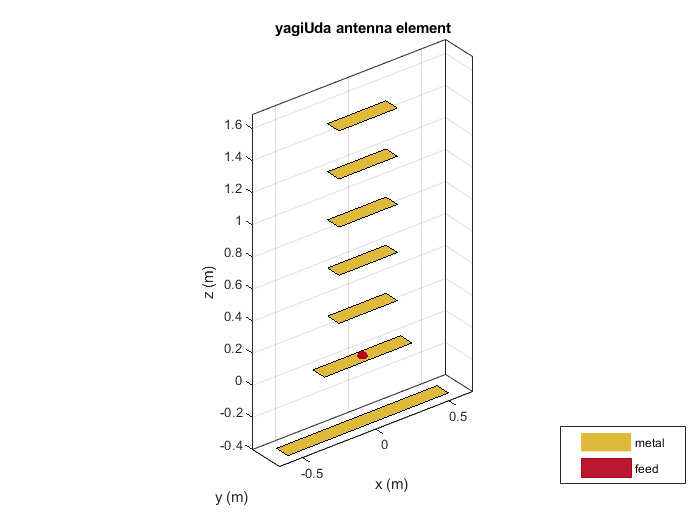

df = dipole;
df.Length = 0.6;
df.Tilt = 90;
df.TiltAxis = 'Y';

y = yagiUda('Exciter', df, 'NumDirectors',5, ...
    'DirectorLength', 0.4, 'DirectorSpacing', 0.3, ...
    'ReflectorLength', 1.1, 'ReflectorSpacing', 0.4);
show(y)

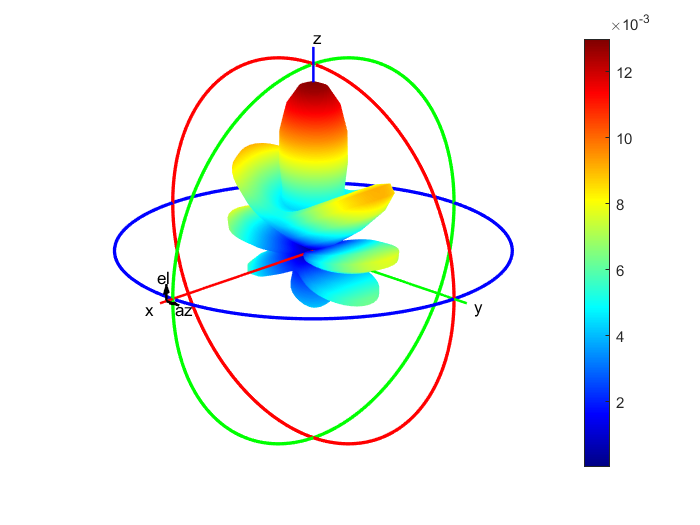

figure;
[efield, az, el] = pattern(y, 300e6, 'Type', 'efield');
phi = az';
theta = (90-el);
MagE = efield';
patternCustom(MagE, theta, phi)

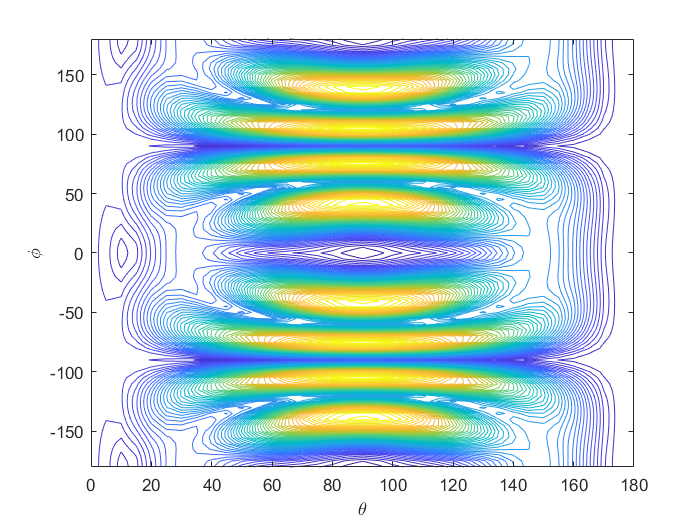

[X, Y] = meshgrid(theta, phi);

figure;
contour(X, Y, MagE, 50);
xlabel('\theta');
ylabel('\phi');
axis([0, 180, -180, 180]);

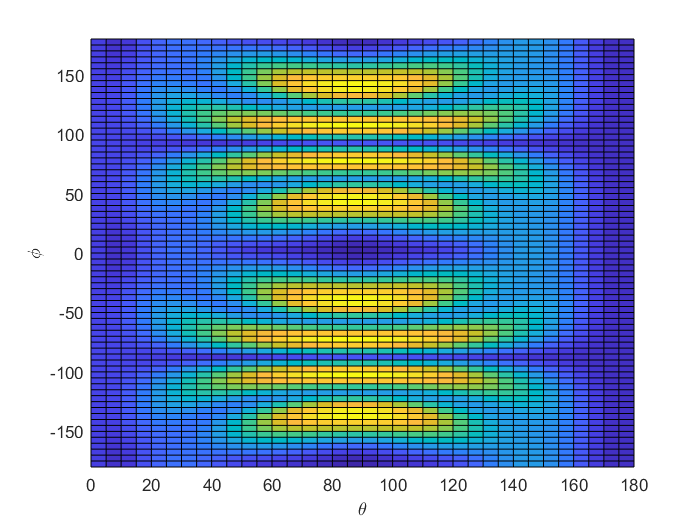

figure;
surf(X, Y, MagE);
xlabel('\theta');
ylabel('\phi');
axis([0, 180, -180, 180]);
view(2)

drawnow
